# Compute $\pi$, naive version

Compute area of the unit circle

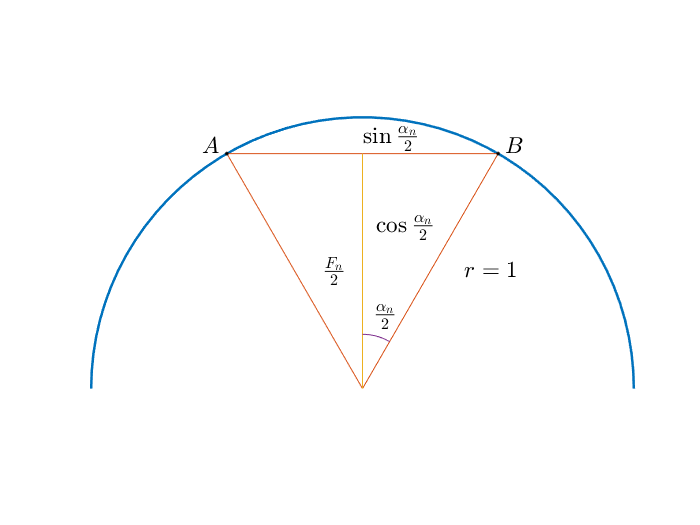

Area of the triangle is


$$F_{n}=\cos\frac{\alpha_{n}}{2}\sin\frac{\alpha_{n}}{2}$$


where $\alpha_{n}=\frac{2\pi}{n}$. The total area is


$$A_n=n F_n=\frac{n}{2}\sin \alpha_{n}=\frac{n}{2}\sin\frac{2\pi}{n}.$$


Recurrence relation


$$\sin\frac{\alpha_{n}}{2}=\sqrt{\frac{1-\cos \alpha_{n}}{2}}=\sqrt{\frac{1-\sqrt{1-\sin^2 \alpha_{n}}}{2}}$$


## Initialization

$n=6$, $\alpha_{6}=\frac{\pi}{3}$, $A_{6}=3\frac{\sqrt{3}}{2}$, $\sin\alpha_{6}=\frac{\sqrt{3}}{2}$.

s=sqrt(3)/2; A=3*s; n=6; % initialization
z=[A-pi n A s]; % store the results
while s>1e-10 % termination if s=sin(alpha) small
    s=sqrt((1-sqrt(1-s*s))/2); % new sin(alpha/2) value
    n=2*n; A=n/2*s; % A=new polygon area
    z=[z; A-pi n A s];
end
m=length(z);
for i=1:m
    fprintf('%10d %20.15f %20.15f %20.15f\n',...
        z(i,2),z(i,3),z(i,1),z(i,4))
end

         6    2.598076211353316   -0.543516442236477    0.866025403784439
        12    3.000000000000000   -0.141592653589794    0.500000000000000
        24    3.105828541230250   -0.035764112359543    0.258819045102521
        48    3.132628613281237   -0.008964040308556    0.130526192220052
        96    3.139350203046872   -0.002242450542921    0.065403129230143
       192    3.141031950890530   -0.000560702699263    0.032719082821776
       384    3.141452472285344   -0.000140181304449    0.016361731626486
       768    3.141557607911622   -0.000035045678171    0.008181139603937
      1536    3.141583892148936   -0.000008761440857    0.004090604026236
      3072    3.141590463236762   -0.000002190353031    0.002045306291170
      6144    3.141592106043048   -0.000000547546745    0.001022653680353
     12288    3.141592516588155   -0.000000137001638    0.000511326906997
     24576    3.141592618640789   -0.000000034949004    0.000255663461803
     49152    3.141592645321216   -0.0